**Lab 1 Notebook**

Liangzhe Liu, 1663973

**A Little Statistics**

**2. **

*Lognormal Distribution*

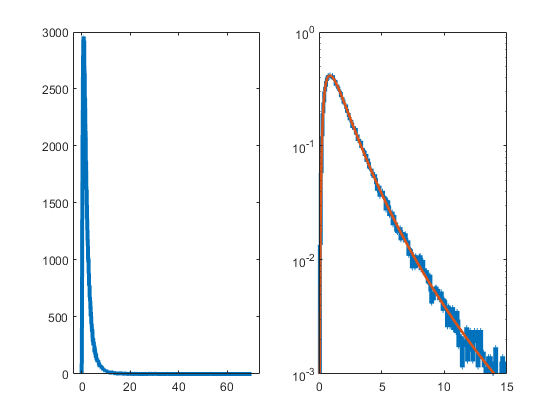

% Create a Lognormal Distribution data set with 0.5 as mean and 0.8 as sigma.
logd = random('Lognormal',0.5,0.8,[1,100000]); 
subplot(1,2,1)
% Plot the data set.
histogram(logd,1000,'DisplayStyle',"stairs",'LineWidth',3) 
subplot(1,2,2)
% Plot the data set in log with the pdf curve fit.
histogram(logd,1000,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf") 
hold on
logx = linspace(0,50,1000);
logN = makedist("Lognormal",'mu',0.5,'sigma',0.8);
plot(logx,pdf(logN,logx),"LineWidth",2)
set(gca,'YScale','log')
ylim([1e-3,1])
xlim([0,15])
hold off

*Exponential Distribution*

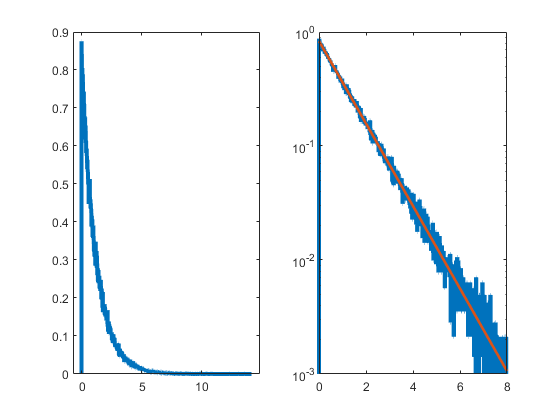

% Create a Exponential Distribution data set with 1.2 as mean.
expd = exprnd(1.2,[1,100000]);
subplot(1,2,1)
% Plot the data set.
histogram(expd,1000,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
subplot(1,2,2)
% Plot the data set in log with the pdf curve fit.
histogram(expd,1000,'DisplayStyle',"stairs",'LineWidth',3,"Normalization","pdf")
hold on
expx = linspace(0,30,1000);
expD = makedist("Exponential",'mu',1.2);
plot(expx,pdf(expD,expx),"LineWidth",2);
set(gca,'YScale','log')
ylim([1e-3,1])
xlim([0,8])
hold off

**3. **

A. I would choose 10 as my value for my hypothetical measurement with Lognormal Distribution

B. What is the probability that this data set of Lognormal Distribution with mean as 0.5 and sigma as 0.8 produces a signal that is equally or more signal-like than what it is like?

C. $\int_{10}^{\infty } \frac{1}{x\sigma \sqrt{2\pi }}e^{-\frac{{\left(\ln \left(x\right)-\mu \right)}^2 }{2\sigma^2 }}$

D. The probability at the set value 10 in this distribution.

c = cdf(logN,10)

c = 0.9879

E. The "sigma" for the set value 10.

sigmalogN = norminv(c)

sigmalogN = 2.2532

**4.** 

c1 = cdf(logN,8)

c1 = 0.9758

sigmalogN1 = norminv(c1)

sigmalogN1 = 1.9743

c2 = cdf(logN,12)

c2 = 0.9935

sigmalogN2 = norminv(c2)

sigmalogN2 = 2.4811

pc = icdf(logN,0.5) % returns the value when the probability is 0.5

pc = 1.6487

c3 = cdf(logN, pc)

c3 = 0.5000

sigmalogN3 = norminv(c3)

sigmalogN3 = 0

c4 = cdf(logN,1)

c4 = 0.2660

sigmalogN4 = norminv(c4)

sigmalogN4 = -0.6250

The probability is 0.5 when the hypothetical measurement value is 1.6487. And for the values larger than 1.6487, the probability and the "sigma" is increased with larger values. For values smaller than 1.6487, the probability is decreased with smaller values but the absolute value of the "sigma" is increasing, because they are further away from 1.6487.

**Non-continuous distributions**

B.

Poisson Distribution

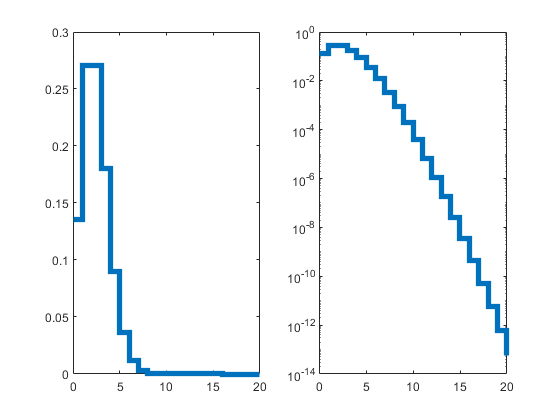

p = 0:20;
% Set the mean value for Poisson Distribution to 2.
poisson2 = makedist("Poisson",'lambda',2); 
subplot(1,2,2)
stairs(p, pdf(poisson2,p),"LineWidth",4);
set(gca,'YScale','log')
subplot(1,2,1)
stairs(p,pdf(poisson2,p),"LineWidth",4);
% Set the plot for Poisson distribution for each case the same 
% to get a clear view of the trend when parameters changed
ylim([0,0.3])
xlim([0,20])

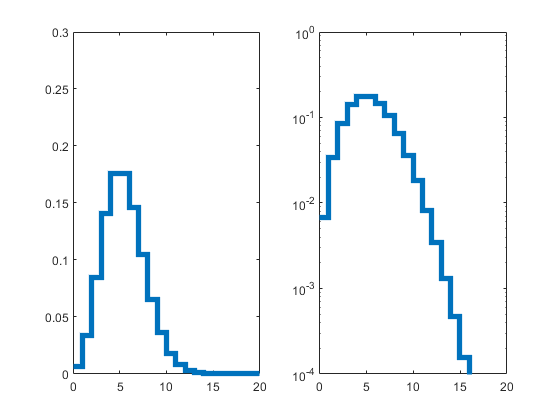

% Set the mean value for Poisson Distribution to 5.
poisson5 = makedist("Poisson",'lambda',5); 
subplot(1,2,2)
stairs(p, pdf(poisson5,p),"LineWidth",4);
ylim([1e-4,1])
xlim([0,20])
set(gca,'YScale','log')
subplot(1,2,1)
stairs(p,pdf(poisson5,p),"LineWidth",4);
ylim([0,0.3])
xlim([0,20]) 

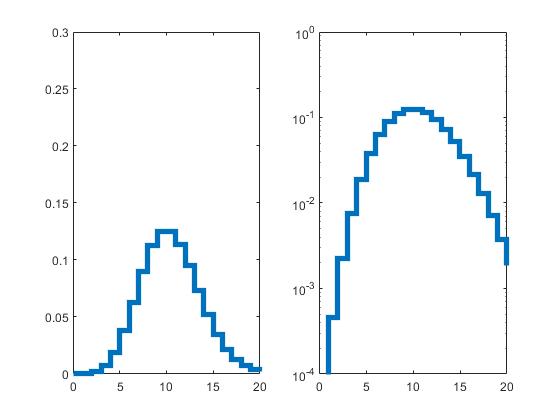

% Set the mean value for Poisson Distribution to 10.
poisson10 = makedist("Poisson",'lambda',10); 
subplot(1,2,2)
stairs(p, pdf(poisson10,p),"LineWidth",4);
ylim([1e-4,1])
xlim([0,20])
set(gca,'YScale','log')
subplot(1,2,1)
stairs(p,pdf(poisson10,p),"LineWidth",4);
ylim([0,0.3])
xlim([0,20]) 

C. What is the probability that this data set of Poisson Distribution with mean value as 10 produces a signal that is equally or more signal-like than what it is like for signal value as 10?

nc = cdf(poisson10,10)

nc = 0.5830

poissonSigma = norminv(nc)

poissonSigma = 0.2097

D. In experiments, when we get some data set in which the probability distribution function and sigmas are not continuous, we need to think about to fit a Poisson distribution for this data set or other non-continuous distribution.

E. Because Poisson Distribution has only one parameter, which is mean, and mean value is not necessary to be in part of the data set in this Poisson Distribution. For example, in an experiment, the mean value from a large data set might not be equal to any data in this data set. Therefore, the mean value, aka lamda, can change continuously, but the data in this data set that fits Poisson distribution and the probabilities or the "sigmas" of these data cannot.